%----straight line initial condition

%number of points in the trajectory
traj_pt = 500;

%List of roots
pos_root_arr = double(pos_root_arr)

pos_root_arr =     1.0000    1.0000
    2.0000    2.0000
    2.1654    1.0930
    1.0930    2.1654
    2.8367    1.1633
    1.1633    2.8367
    3.0000    3.0000
    2.9070    1.8346
    1.8346    2.9070



%start & end point
start_idx = 7; end_idx = 8;

%get straight line initial condition joining the end points
q_IC = straight_line_IC(traj_pt,pos_root_arr,start_idx,end_idx);


%For descent 
traj = q_IC;

num_smooth = 10

%Initialize Descender by getting a phase space (PS) trajectory from x_ic
Initialize_descender

S_arr =    0.007878163177299


%Plot initial Phase space trajectory

ans =    0.007878163177299


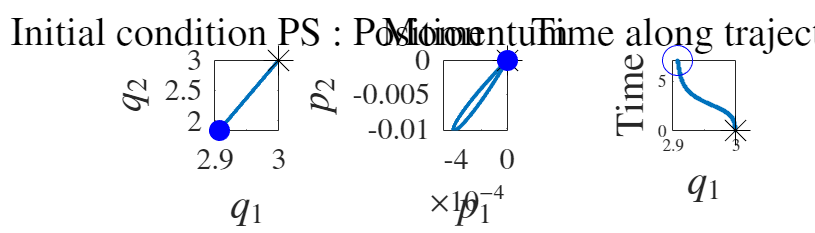

plotnam = "Initial condition PS";
save_plot_name = 'Examples\Plots\'+model_nam+'_IC_PS_traj.png';
save_plot_flag = 0; %change to 1 to save
plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,save_plot_flag)

%Create a .mat file for saving data
savenam = 'Examples\Data\' + model_nam + '_descend_'+string(start_idx)...
    +'_'+string(end_idx)+'_straightIC_'+string(traj_pts)+'_'+string(date)+'.mat'

savenam = "Examples\Data\2Schlogl_descend_7_8_straightIC_500_13-Oct-2023.mat"

## Actual descent

%Actual descender parameters

%step size
eps_ic = 1; eps = eps_ic; eps_min = 0.01;    

%Action threshold settings
delta_S = 10; err_thresh = 10^(-1); 
eps_S_thresh = 10^(-7); delta_S_thresh = 10^(-7);
delta_S_thresh_eps = 10^(-7);

%low pass filter settings
f0 =5; f0_max = 40; f0_step = 0.1; 
time_uniform_f = 45;

%Distance to Hamilton's EoM settings
 a_min=100; a_thresh = 0.001;

%iteration settins
iter_max = 4; iter = 1;

format long

while f0<f0_max  &&  iter<iter_max && a_min>a_thresh
    iter = iter + 1;
    traj_pts = size(traj,1);

    %take a step in the gradient by picking appropriate step size
    [eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
        (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,delta_x_s,action_S,eps,num_smooth,eps_min,delta_S_thresh_eps);
    traj = PS_traj(:,1:num_spec);
    delta_S = action_S_new - action_S;
    [iter, eps, action_S_new, delta_S, f0]
    eps_used = eps;

    
    f0

    if abs(delta_S)<delta_S_thresh || eps < eps_min
        f0 = f0 + 0.1; eps = eps_ic; delta_S = 1;  
        traj = time_uniform_filter(traj,t_traj,traj_pts,time_uniform_f);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
    end

    
    %smoothen gradient for next iteration
    delta_x_s =  smooth_traj_butter(delta_x,f0); 

    %Find closest distance by integrating HamEoM
    a_min = ham_closest_approach_noplot(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)

    
    %Update descender and save to file
    Update_descender
    save(savenam)
    
    %Plot some stuff in every some iterations
    if mod(iter,10)==0
        save_plot_name = save_plot_name_root +'_deltax_'+string(iter)+'.png'
        debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,1);
        save_plot_name = save_plot_name_root +'_PS_traj_'+string(iter)+'.png'
        plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,1);
        save_plot_name = save_plot_name_root + '_HamEoM_' + string(iter)+'.png';
        a = ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)
    end

    
end

delta_S =     -1.019797265097364e-06


ans =    2.000000000000000   1.000000000000000   0.007873332347879  -0.000001019797265   5.000000000000000


f0 =      5


a_min =    0.360457637501656


delta_S =     -7.896089704428205e-07


ans =    3.000000000000000   1.000000000000000   0.007872542738909  -0.000000789608970   5.000000000000000


f0 =      5


a_min =    0.355491258469971


delta_S =     -6.874449117906523e-07


ans =    4.000000000000000   1.000000000000000   0.007871855293997  -0.000000687444912   5.000000000000000


f0 =      5


a_min =    0.350602243941519


format short

f0_arr

f0_arr =     3.0000
    3.0000
    5.2000
    5.3000
    5.0000
    5.0000
    5.0000


format long
S_arr(end)

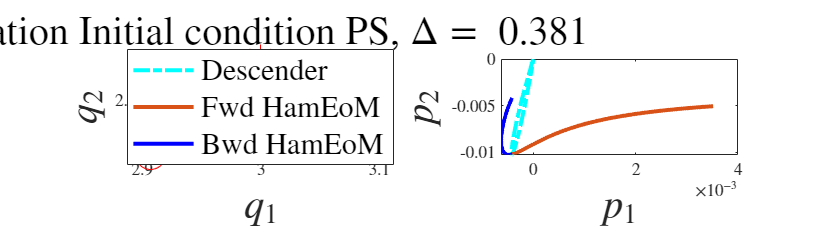

a_min =    0.381082645636494


    a_min = ham_closest_approach(PS_traj,S_traj,t_traj,dHamdp_fun, dHamdq_fun,save_plot_name,1,plotnam)

size(conc_traj)

ans =    100000001           4


format long
anneal_ct = 0;
while f0<f0_max  &&  iter<iter_max
    iter = iter + 1;
    traj_pts = size(traj,1);


    %take a step in the gradient by picking appropriate step size
    [eps, action_S_new, PS_traj, t_traj, delta_x, S_traj] = eps_picker...
        (traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,...
        delta_x_s,action_S,eps,num_smooth,eps_min,delta_S_thresh);
    traj = PS_traj(:,1:num_spec);
    delta_S = action_S_new - action_S;
    [iter, eps, action_S_new, delta_S, f0]
    eps_used = eps;
    %if delta_S is positive, then break. If less than threshold then
    %increase cutoff frequency. If descent has stopped, anneal.
    %{
    if delta_S > 0
        disp('Why is action increasing? Error!')
        break
    
    elseif eps == 0
        anneal_ct = anneal_ct + 1;
        f0 = f0 - 0.1; eps = 0.5; delta_S = 1; traj_pts_new = traj_pts;
        if anneal_ct >2
            disp('Annealing')
            traj_pts_new = traj_pts+1000;
            f0 = f0; eps = 1; delta_S = 1;  traj_pts = traj_pts_new;
            anneal_ct = 0;
        end
        traj = time_uniform_filter(traj,t_traj,traj_pts_new,35);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
        %}
    if f0 > 6
        f0 = f0; eps = 0.5; delta_S = 1; traj_pts_new = traj_pts;
        traj_pts_new = traj_pts+1000;
        traj = time_uniform_filter(traj,t_traj,traj_pts_new,35);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    

    elseif abs(delta_S)<delta_S_thresh || eps < eps_min
        f0 = f0 + 0.1; eps = 1; delta_S = 1;  
        traj = time_uniform_filter(traj,t_traj,traj_pts,35);
        [traj,len_curve_prime] = space_uniform_sampling(traj,traj_pts);
        [PS_traj, t_traj, delta_x] = traj_2_PS_traj_func(traj,eqns_fsolve_fun,Jac_eqns_fsolve_fun,dHamdq_fun,Ham_fun_qp,num_smooth);    
    end

    
    %smoothen gradient for next iteration
    delta_x_s =  smooth_traj_butter(delta_x,f0); 

    
    %Update descender and save to file
    Update_descender
    save(savenam)
    
    %Plot some stuff in every some iterations
    if mod(iter,5)==0
        save_plot_name = 'Plots/'+model_name+'_'+string(sad_pt)...
        +'_'+string(stab_pt_choice)+'_deltax_'+string(iter)+'.png'
        plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,0);
        debugging_deltax_plots(delta_x,delta_x_s,f0,plotnam,save_plot_name,0);
    end

    
end
